# Reflectance analysis

We have individual measurements of tongue and lip reflectance.  We analyze them here and then use them for the figure showing that the bulk fluorescence levels exceed the reflectance levels, individual by individual.

See also:

ieInit;
wave = 500:700;
subjects = {'B','J','Z','D'};

meanTongue = ieReadSpectra('tongue',wave);
for jj=1:size(meanTongue,2)
    meanTongue(:,jj) = meanTongue(:,jj)/meanTongue(wave==520,jj);
end

## Create reflectance from raw data

The raw data and calibration should be in the subdirectory data/reflectance/raw within the oe ... repository.

## Tongue reflectance

These subjects are just like the subjects measured in the past and stored in isetcam.

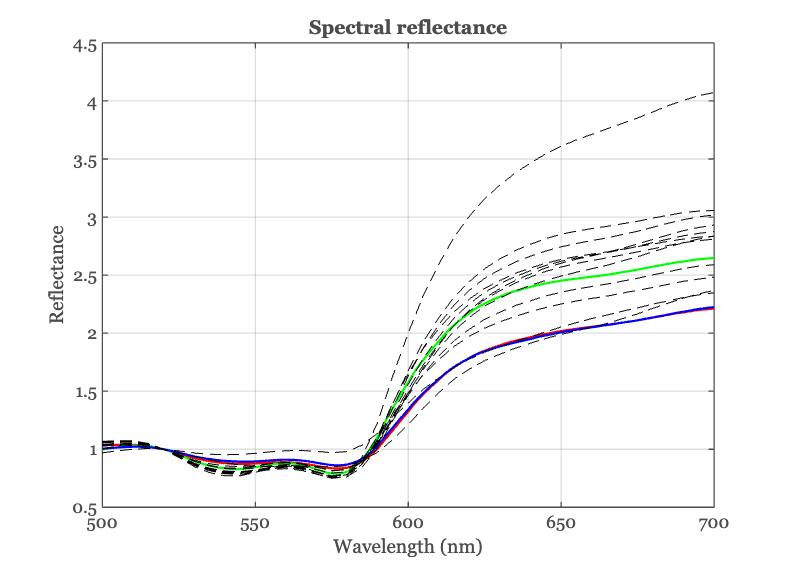

hdl = ieFigure;

for ii=1:(numel(subjects)-1)
    r = ieReadSpectra([subjects{ii},'_tongueReflectance'],wave);
    plotReflectance(wave,r/r(wave==520),'hdl',hdl); hold on
end

plotReflectance(wave,meanTongue,'Color','k','line style','--','hdl',hdl,'linewidth',0.5);

## Lip reflectance

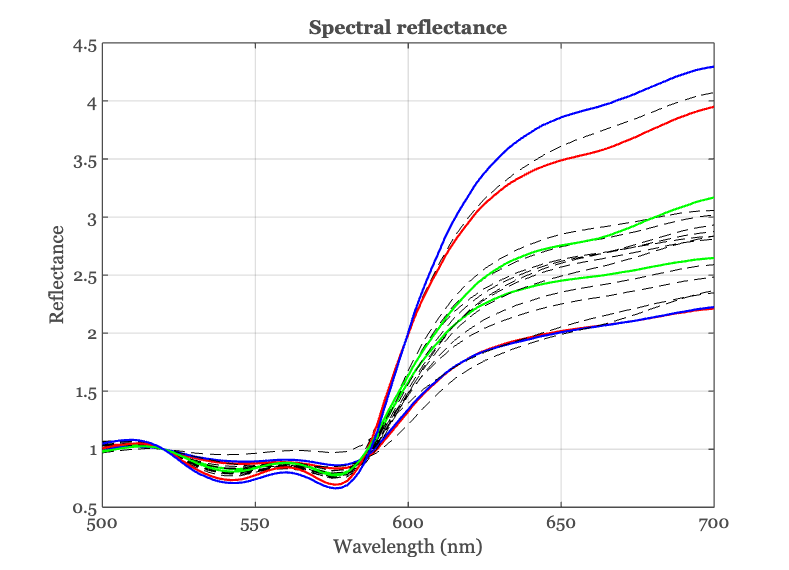

% hdl = ieFigure;

for ii=1:(numel(subjects)-1)
    r = ieReadSpectra([subjects{ii},'_lipReflectance'],wave);
    plotReflectance(wave,r/r(wave==520),'hdl',hdl); hold on
end

% plotReflectance(wave,meanTongue,'Color','k','line style','--','hdl',hdl,'linewidth',0.5);
set(gca,'yscale','linear');